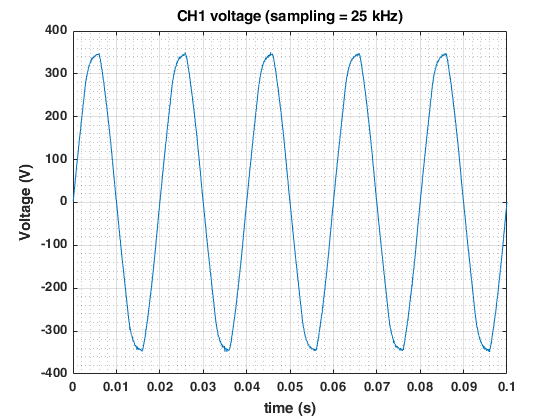

close all;
clear;


proj_folder = "C:\Users\VMORAIS\Development\20210829 - SummerSchool_proj\2. data\";%uigetdir();

%% load CSV files
meas1 = importfile(strcat(proj_folder, "demo1\meas1.csv"), [2, Inf]);
meas2 = importfile(strcat(proj_folder, "demo1\meas2.csv"), [2, Inf]);
%meas3 = importfile(strcat(proj_folder, "demo1\meas3.csv"), [2, Inf]);



%% fix time vectors for each measurement
meas1.Timestamp = ((1:1:size(meas1,1)) .* (0.1/size(meas1,1))).';
meas2.Timestamp = ((1:1:size(meas2,1)) .* (0.1/size(meas2,1))).';


%% plot measurements
plot(meas1.Timestamp, meas1.V_ch1);
grid on; grid minor; xlabel('time (s)'); ylabel("Voltage (V)"); title("CH1 voltage (sampling = 25 kHz)");

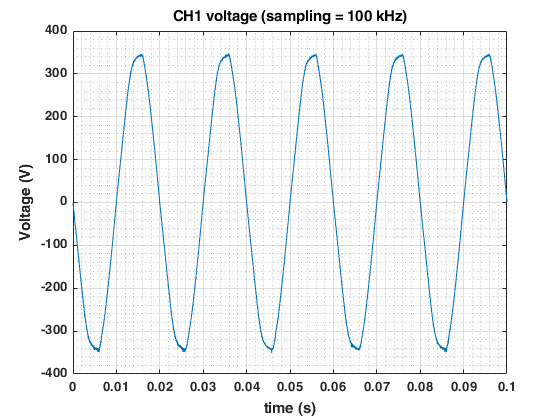

plot(meas2.Timestamp, meas2.V_ch1);
grid on; grid minor; xlabel('time (s)'); ylabel("Voltage (V)"); title("CH1 voltage (sampling = 100 kHz)");

function meas1 = importfile(filename, dataLines)
%IMPORTFILE Import data from a text file
%  MEAS1 = IMPORTFILE(FILENAME) reads data from text file FILENAME for
%  the default selection.  Returns the data as a table.
%
%  MEAS1 = IMPORTFILE(FILE, DATALINES) reads data for the specified row
%  interval(s) of text file FILENAME. Specify DATALINES as a positive
%  scalar integer or a N-by-2 array of positive scalar integers for
%  dis-contiguous row intervals.
%
%  Example:
%  meas1 = importfile("C:\Users\VMORAIS\Development\20210829 - SummerSchool_proj\2. data\demo1\meas1.csv", [2, Inf]);
%
%  See also READTABLE.
%
% Auto-generated by MATLAB on 29-Aug-2021 16:43:08

%% Input handling

% If dataLines is not specified, define defaults
if nargin < 2
    dataLines = [2, Inf];
end

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Timestamp", "V_ch1", "V_ch2", "V_ch3", "I_ch1", "I_ch2", "I_ch3"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
meas1 = readtable(filename, opts);

end